# **雷达信号处理和自动驾驶联合仿真**

本例子用于展示如何建模雷达硬件，信号处理，传播环境对于自动驾驶场景。

第一步，你需要采用相控阵工具箱建模雷达发射机，接收机，信号处理，目标探测和距离估计。下一步，使用自动驾驶工具箱建模车辆运动和跟踪合成车辆探测。在本例中，你要使用雷达模型在高速驾驶场景中进行跟踪探测。

## **引言**

你可以通过自动驾驶工具箱使用 drivingScenario 对象建模车辆运动。车辆地面的真实情况可以使用合成传感器检测，通过使用multiObjectTracker 对象来实现。对于这个工作流程举例，请参考[Sensor Fusion Using Synthetic Radar and Vision Data](docid:driving_examples.mw_4b0a3201-1e7b-487f-961c-8f0ebf14df97).在这个例子中，汽车雷达的使用时根据高级雷达参数化规范的统计模型。在该示例中建模的通用雷达架构不包括天线的配置，波形以及传播信道的特性建模。当我们设计汽车雷达，或者已知雷达的特定架构时，建议使用包含这些附加信息的雷达模型。

相控阵工具箱是你可以评估不同的雷达架构。你可以探索不同的发射和接收阵列设置，波形和信号处理流程。你也可以根据不同的信道模型来评估你的设计，来判断对不同环境下雷达工作的鲁棒性。此模型帮助你确定最适合您应用要求和特定设计。

 在这个例子中，你要学习如何根据远程雷达的一系列系统要求定义雷达模型。然后，你可以模拟驾驶场景，以便从雷达模型中生成检测结果。跟踪器用于处理这些检测，以生成汽车雷达检测到的车辆位置和速度的精确估计。

## **从远程雷达要求中计算雷达参数**

雷达参数是针对调频连续波(FMCW)波形定义的，如例子[Automotive Adaptive Cruise Control Using FMCW Technology](docid:phased_examples.example-ex11665805)中描述的。该雷达工作的中心频率为77GHz。这个频率常用于汽车雷达中。对于长距工作，雷达必须探测自身车辆前方最大范围100m以内的车辆。雷达需要的距离分辨率至少1m。因为这是一个前向雷达应用场景，同时雷达还需要处理具有大闭合速度的目标，高达230km/h.雷达设计使用FMCW波形。这些波形在汽车应用中很常见，因为他们通过高效的FFT运算实现距离和多普勒估计。

% 设置随机数生成器保证结果一致
rng(2017);

% 根据长距离要求计算硬件参数
fc = 77e9;                                      % 中心频率
c = physconst('LightSpeed');                    % 光速
lambda = c/fc;                                  % 波长

% 设置扫频时间为最大探测距离的5倍
rangeMax = 100;                                 % 最大探测距离
tm = 5*range2time(rangeMax,c);                  % 扫频时间

% Determine the waveform bandwidth from the required range resolution
rangeRes = 1;                                   % Desired range resolution (m)
bw = range2bw(rangeRes,c);                      % Corresponding bandwidth (Hz)

% Set the sampling rate to satisfy both the range and velocity requirements
% for the radar
sweepSlope = bw/tm;                             % FMCW sweep slope (Hz/s)
fbeatMax = range2beat(rangeMax,sweepSlope,c);   % Maximum beat frequency (Hz)

vMax = 230*1000/3600;                           % Maximum Velocity of cars (m/s)
fdopMax = speed2dop(2*vMax,lambda);             % Maximum Doppler shift (Hz)

fifMax = fbeatMax+fdopMax;                      % Maximum received intermediate frequency (IF) (Hz)
fs = max(2*fifMax,bw);                          % Sampling rate (Hz)

% Configure the FMCW waveform using the waveform parameters derived from
% the long-range requirements
waveform = phased.FMCWWaveform('SweepTime',tm,'SweepBandwidth',bw,'SampleRate',fs);
Nsweep = 192;

## Model Automotive Radar Hardware

The radar uses a uniform linear array (ULA) to transmit and receive the radar waveforms. Using a linear array enables the radar to estimate the azimuthal direction of the reflected energy received from the target vehicles. The long-range radar needs to detect targets across a coverage area that spans 15 degrees in front of the ego vehicle. A 6-element receive array satisfies this requirement by providing a 16 degree half-power beamwidth. On transmit, the radar uses only a single array element, enabling it to cover a larger area than on receive.

% Model the antenna element
antElmnt = phased.IsotropicAntennaElement('BackBaffled',true);

% Construct the receive array
Ne = 6;
rxArray = phased.ULA('Element',antElmnt,'NumElements',Ne,'ElementSpacing',lambda/2);

% Form forward-facing beam to detect objects in front of the ego vehicle
beamformer = phased.PhaseShiftBeamformer('SensorArray',rxArray,...
    'PropagationSpeed',c,'OperatingFrequency',fc,'Direction',[0;0]);

% Half-power beamwidth of the receive array
helperAutoDrivingRadarSigProc('Array Beamwidth',rxArray,c,fc)

Estimate the direction-of-arrival of the received signals using a root MUSIC estimator. A beamscan is also used for illustrative purposes to help spatially visualize the distribution of the received signal energy.

% Direction-of-arrival estimator for linear phased array signals
doaest = phased.RootMUSICEstimator(...
    'SensorArray',rxArray,...
    'PropagationSpeed',c,'OperatingFrequency',fc,...
    'NumSignalsSource','Property','NumSignals',1);

% Scan beams in front of ego vehicle for range-angle image display
angscan = -80:80;
beamscan = phased.PhaseShiftBeamformer('Direction',[angscan;0*angscan],...
    'SensorArray',rxArray,'OperatingFrequency',fc);

Model the radar transmitter for a single transmit channel, and model a receiver preamplifier for each receive channel, using the parameters defined in the example [Automotive Adaptive Cruise Control Using FMCW Technology](docid:phased_examples.example-ex11665805).

antAperture = 6.06e-4;                          % Antenna aperture (m^2)
antGain = aperture2gain(antAperture,lambda);    % Antenna gain (dB)

txPkPower = db2pow(5)*1e-3;                     % Tx peak power (W)
txGain = antGain;                               % Tx antenna gain (dB)

rxGain = antGain;                               % Rx antenna gain (dB)
rxNF = 4.5;                                     % Receiver noise figure (dB)

% Waveform transmitter
transmitter = phased.Transmitter('PeakPower',txPkPower,'Gain',txGain);

% Radiator for single transmit element
radiator = phased.Radiator('Sensor',antElmnt,'OperatingFrequency',fc);

% Collector for receive array
collector = phased.Collector('Sensor',rxArray,'OperatingFrequency',fc);

% Receiver preamplifier
receiver = phased.ReceiverPreamp('Gain',rxGain,'NoiseFigure',rxNF,'SampleRate',fs);

## Define Radar Signal Processing Chain

The radar collects multiple sweeps of the waveform on each of the linear phased array antenna elements. These collected sweeps form a data cube, which is defined in [Radar Data Cube](docid:phased_gs.bsmig5l-1). These sweeps are coherently processed along the fast- and slow-time dimensions of the data cube to estimate the range and Doppler of the vehicles.

Use the `phased.RangeDopplerResponse` object to perform the range and Doppler processing on the radar data cubes. Use a Hanning window to suppress the large sidelobes produced by the vehicles when they are close to the radar.

Nft = waveform.SweepTime*waveform.SampleRate; % Number of fast-time samples
Nst = Nsweep;                                 % Number of slow-time samples
Nr = 2^nextpow2(Nft);                         % Number of range samples after processing
Nd = 2^nextpow2(Nst);                         % Number of Doppler samples after processing
rngdopresp = phased.RangeDopplerResponse('RangeMethod','FFT','DopplerOutput','Speed',...
    'SweepSlope',sweepSlope,...
    'RangeFFTLengthSource','Property','RangeFFTLength',Nr,...
    'RangeWindow','Hann',...
    'DopplerFFTLengthSource','Property','DopplerFFTLength',Nd,...
    'DopplerWindow','Hann',...
    'PropagationSpeed',c,'OperatingFrequency',fc,'SampleRate',fs);

Identify detections in the processed range and Doppler data by using a constant false alarm rate (CFAR) detector. CFAR detectors estimate the background noise level of the received radar data. Detections are found at locations where the signal power exceeds the estimated noise floor by a certain threshold. Low threshold values result in a higher number of reported false detections due to environmental noise. Increasing the threshold produces fewer false detections, but also reduces the probability of detection of an actual target in the scenario. For more information on CFAR detection, see the example [Constant False Alarm Rate (CFAR) Detection](docid:phased_examples.example-ex14061099).

% Guard cell and training regions for range dimension
nGuardRng = 4;
nTrainRng = 4;
nCUTRng = 1+nGuardRng+nTrainRng;

% Guard cell and training regions for Doppler dimension
dopOver = round(Nd/Nsweep);
nGuardDop = 4*dopOver;
nTrainDop = 4*dopOver;
nCUTDop = 1+nGuardDop+nTrainDop;

cfar = phased.CFARDetector2D('GuardBandSize',[nGuardRng nGuardDop],...
    'TrainingBandSize',[nTrainRng nTrainDop],...
    'ThresholdFactor','Custom','CustomThresholdFactor',db2pow(13),...
    'NoisePowerOutputPort',true,'OutputFormat','Detection index');

% Perform CFAR processing over all of the range and Doppler cells
freqs = ((0:Nr-1)'/Nr-0.5)*fs;
rnggrid = beat2range(freqs,sweepSlope);
iRngCUT = find(rnggrid>0);
iRngCUT = iRngCUT(iRngCUT<=Nr-nCUTRng+1);
iDopCUT = nCUTDop:(Nd-nCUTDop+1);
[iRng,iDop] = meshgrid(iRngCUT,iDopCUT);
idxCFAR = [iRng(:) iDop(:)]';

The `phased.RangeEstimator` and `phased.DopplerEstimator` objects convert the locations of the detections found in the range-Doppler data into measurements and their corresponding measurement variances. These estimators fit quadratic curves to the range-Doppler data to estimate the peak location of each detection. The resulting measurement resolutions are a fraction of the range and Doppler sampling of the data.

The root-mean-square (RMS) range resolution of the transmitted waveform is needed to compute the variance of the range measurements. The Rayleigh range resolution for the long-range radar was defined previously as 1 meter. The Rayleigh resolution is the minimum separation at which two unique targets can be resolved. This value defines the distance between range resolution cells for the radar. However, the variance of the target within a resolution cell is determined by the waveform's RMS resolution. For an LFM chirp waveform, the relationship between the Rayleigh resolution and the RMS resolution is given by [1].


$$\sigma_{RMS} = \sqrt{12}\Delta_{Rayleigh}$$


where $\sigma_{RMS}$ is the RMS range resolution and $\Delta_{Rayleigh}$ is the Rayleigh range resolution.

The variance of the Doppler measurements depends on the number of sweeps processed.

Now, create the range and Doppler estimation objects using the parameters previously defined.

rmsRng = sqrt(12)*rangeRes;
rngestimator = phased.RangeEstimator('ClusterInputPort',true,...
    'VarianceOutputPort',true,'NoisePowerSource','Input port','RMSResolution',rmsRng);

dopestimator = phased.DopplerEstimator('ClusterInputPort',true,...
    'VarianceOutputPort',true,'NoisePowerSource','Input port','NumPulses',Nsweep);

To further improve the precision of the estimated vehicle locations, pass the radar's detections to a tracker. Configure the track to use an extended Kalman filter (EKF), which converts the spherical radar measurements into the ego vehicle's Cartesian coordinate frame. Also configure the tracker to use constant velocity dynamics for the detected vehicles. By comparing vehicle detections over multiple measurement time intervals, the tracker further improves the accuracy of the vehicle positions and provides vehicle velocity estimates.

tracker = multiObjectTracker('FilterInitializationFcn',@initcvekf,'AssignmentThreshold',50);

## Model Free Space Propagation Channel

Use the free space channel to model the propagation of the transmitted and received radar signals.

channel = phased.FreeSpace('PropagationSpeed',c,'OperatingFrequency',fc,...
    'SampleRate',fs,'TwoWayPropagation',true);

In a free space model, the radar energy propagates along a direct line-of-sight between the radar and the target vehicles, as shown in the following illustration.

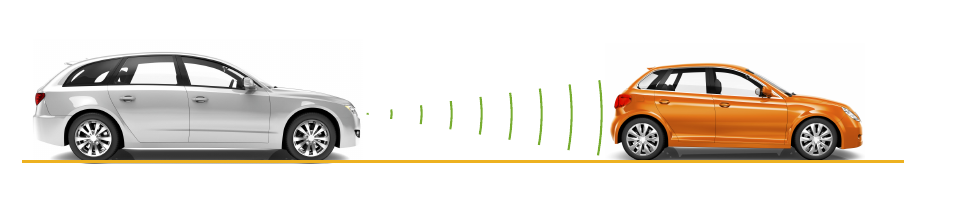

## Simulate the Driving Scenario

Create a highway driving scenario with three vehicles traveling in the vicinity of the ego car. The vehicles are modeled as point targets, and have different velocities and positions defined in the driving scenario. The ego car is moving with a velocity of 80 km/hr and the other three cars are moving at 110 km/hr, 100 km/hr, and 130 km/hr respectively. For details on modeling a driving scenario, see the example [Create Actor and Vehicle Paths](docid:driving_examples.mw_165f4466-8fd6-4fba-9659-b9b9d83ec3d3). The radar sensor is mounted on the front of the ego car.

% Create driving scenario
[scenario,egoCar,radarParams,pointTgts] = helperAutoDrivingRadarSigProc('Setup Scenario',c,fc);

The following loop uses the `drivingScenario` object to advance the vehicles in the scenario. At every simulation time step, a radar data cube is assembled by collecting 192 sweeps of the radar waveform. The assembled data cube is then processed in range and Doppler. The range and Doppler processed data is then beamformed, and CFAR detection is performed on the beamformed data. Range, radial speed, and direction of arrival measurements are estimated for the CFAR detections. These detections are then assembled into `objectDetection` objects, which are then processed by the `multiObjectTracker` object.

% Initialize display for driving scenario example
helperAutoDrivingRadarSigProc('Initialize Display',egoCar,radarParams,rxArray,fc,vMax,rangeMax);

tgtProfiles = actorProfiles(scenario);
tgtProfiles = tgtProfiles(2:end);
tgtHeight = [tgtProfiles.Height];

% Run the simulation loop
sweepTime = waveform.SweepTime;
while advance(scenario)
    
    % Get the current scenario time
    time = scenario.SimulationTime;
    
    % Get current target poses in ego car's reference frame
    tgtPoses = targetPoses(egoCar);
    tgtPos = reshape([tgtPoses.Position],3,[]);
    tgtPos(3,:) = tgtPos(3,:)+0.5*tgtHeight; % Position point targets at half of each target's height
    tgtVel = reshape([tgtPoses.Velocity],3,[]);
    
    % Assemble data cube at current scenario time
    Xcube = zeros(Nft,Ne,Nsweep);
    for m = 1:Nsweep
        
        % Calculate angles of the targets viewed by the radar
        tgtAngs = NaN(2,numel(tgtPoses));
        for iTgt = 1:numel(tgtPoses)
            tgtAxes = rotz(tgtPoses(iTgt).Yaw)*roty(tgtPoses(iTgt).Pitch)*rotx(tgtPoses(iTgt).Roll);
            [~,tgtAngs(:,iTgt)] = rangeangle(radarParams.OriginPosition,tgtPos(:,iTgt),tgtAxes);
        end
        
        % Transmit FMCW waveform
        sig = waveform();
        [~,txang] = rangeangle(tgtPos,radarParams.OriginPosition,radarParams.Orientation);
        txsig = transmitter(sig);
        txsig = radiator(txsig,txang);
        txsig = channel(txsig,radarParams.OriginPosition,tgtPos,radarParams.OriginVelocity,tgtVel);
        
        % Propagate the signal and reflect off the target
        tgtsig = pointTgts(txsig,tgtAngs);
        
        % Collect received target echos
        rxsig = collector(tgtsig,txang);
        rxsig = receiver(rxsig);
        
        % Dechirp the received signal
        rxsig = dechirp(rxsig,sig);
        
        % Save sweep to data cube
        Xcube(:,:,m) = rxsig;
        
        % Move targets forward in time for next sweep
        tgtPos = tgtPos+tgtVel*sweepTime;
    end
    
    % Calculate the range-Doppler response
    [Xrngdop,rnggrid,dopgrid] = rngdopresp(Xcube);
    
    % Beamform received data
    Xbf = permute(Xrngdop,[1 3 2]);
    Xbf = reshape(Xbf,Nr*Nd,Ne);
    Xbf = beamformer(Xbf);
    Xbf = reshape(Xbf,Nr,Nd);
    
    % Detect targets
    Xpow = abs(Xbf).^2;
    [detidx,noisepwr] = cfar(Xpow,idxCFAR);
    
    % Cluster detections
    clusterIDs = helperAutoDrivingRadarSigProc('Cluster Detections',detidx);
    
    % Estimate azimuth, range, and radial speed measurements
    [azest,azvar,snrdB] = helperAutoDrivingRadarSigProc('Estimate Angle',doaest,conj(Xrngdop),Xbf,detidx,noisepwr,clusterIDs);
    azvar = azvar+radarParams.RMSBias(1)^2;
    
    [rngest,rngvar] = rngestimator(Xbf,rnggrid,detidx,noisepwr,clusterIDs);
    rngvar = rngvar+radarParams.RMSBias(2)^2;
    
    [rsest,rsvar] = dopestimator(Xbf,dopgrid,detidx,noisepwr,clusterIDs);
    
    % Convert radial speed to range rate for use by the tracker
    rrest = -rsest;
    rrvar = rsvar;
    rrvar = rrvar+radarParams.RMSBias(3)^2;
    
    % Assemble object detections for use by tracker
    numDets = numel(rngest);
    dets = cell(numDets,1);
    for iDet = 1:numDets
        dets{iDet} = objectDetection(time,[azest(iDet) rngest(iDet) rrest(iDet)]',...
            'MeasurementNoise',diag([azvar(iDet) rngvar(iDet) rrvar(iDet)]),...
            'MeasurementParameters',{radarParams},...
            'ObjectAttributes',{struct('SNR',snrdB(iDet))});
    end
    
    % Track detections
    tracks = tracker(dets,time);
    
    % Update displays
    helperAutoDrivingRadarSigProc('Update Display',egoCar,dets,tracks,...
        dopgrid,rnggrid,Xbf,beamscan,Xrngdop);
    
    % Publish snapshot
    helperAutoDrivingRadarSigProc('Publish Snapshot',time>=1.1);
    
    % Collect free space channel metrics
    metricsFS = helperAutoDrivingRadarSigProc('Collect Metrics',radarParams,tgtPos,tgtVel,dets);
end

The previous figure shows the radar detections and tracks for the 3 target vehicles at 1.1 seconds of simulation time. The plot on the upper-left side shows the chase camera view of the driving scenario from the perspective of the ego vehicle (shown in blue). For reference, the ego car is traveling at 80 km/hr and the other three cars are traveling at 110 km/hr (orange car), 100 km/hr (yellow car), and 130 km/hr (purple car).

The right side of the figure shows the bird's-eye plot, which presents a "top down" perspective of the scenario. All of the vehicles, detections, and tracks are shown in the ego vehicle's coordinate reference frame. The estimated signal-to-noise ratio (SNR) for each radar measurement is printed next to each detection. The vehicle location estimated by the tracker is shown in the plot using black squares with text next to them indicating each track's ID. The tracker's estimated velocity for each vehicle is shown as a black line pointing in the direction of the vehicle's velocity. The length of the line corresponds to the estimated speed, with longer lines denoting vehicles with higher speeds relative to the ego vehicle. The purple car's track (ID2) has the longest line while the yellow car's track (ID1) has the shortest line. The tracked speeds are consistent with the modeled vehicle speeds previously listed.

The two plots on the lower-left side show the radar images generated by the signal processing. The upper plot shows how the received radar echos from the target vehicles are distributed in range and radial speed. Here, all three vehicles are observed. The measured radial speeds correspond to the velocities estimated by the tracker, as shown in the bird's-eye plot. The lower plot shows how the received target echos are spatially distributed in range and angle. Again, all three targets are present, and their locations match what is shown in the bird's-eye plot.

Due to its close proximity to the radar, the orange car can still be detected despite the large beamforming losses due to its position well outside of the beam's 3 dB beamwidth. These detections have generated a track (ID3) for the orange car.

## Model a Multipath Channel

The previous driving scenario simulation used free space propagation. This is a simple model that models only direct line-of-sight propagation between the radar and each of the targets. In reality, the radar signal propagation is much more complex, involving reflections from multiple obstacles before reaching each target and returning back to the radar. This phenomenon is known as *multipath propagation*. The following illustration shows one such case of multipath propagation, where the signal impinging the target is coming from two directions: line-of-sight and a single bounce from the road surface.

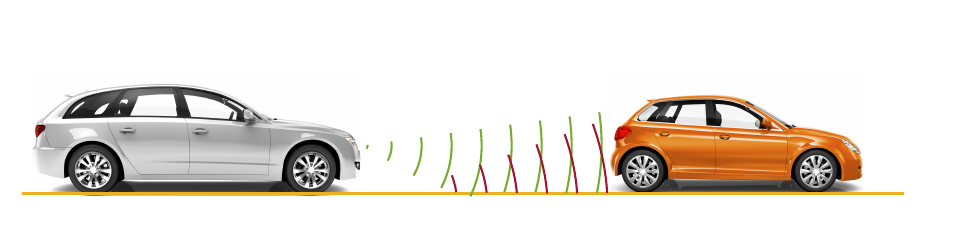

The overall effect of multipath propagation is that the received radar echoes can interfere constructively and destructively. This constructive and destructive interference results from path length differences between the various signal propagation paths. As the distance between the radar and the vehicles changes, these path length differences also change. When the differences between these paths result in echos received by the radar that are almost 180 degrees out of phase, the echos destructively combine, and the radar makes no detection for that range.

Replace the free space channel model with a two-ray channel model to demonstrate the propagation environment shown in the previous illustration. Reuse the remaining parameters in the driving scenario and radar model, and run the simulation again.

% Reset the driving scenario
[scenario,egoCar,radarParams,pointTgts] = helperAutoDrivingRadarSigProc('Setup Scenario',c,fc);

% Create two-ray propagation channels. One channel is used for the transmit
% path and a different channel is used for the receive path.
txchannel = phased.TwoRayChannel('PropagationSpeed',c,'OperatingFrequency',fc,'SampleRate',fs);
rxchannel = phased.TwoRayChannel('PropagationSpeed',c,'OperatingFrequency',fc,'SampleRate',fs);

% Run the simulation again, now using the two-ray channel model
metrics2Ray = helperAutoDrivingRadarSigProc('Run Simulation',...
    c,fc,rangeMax,vMax,waveform,Nsweep,...                  % Waveform parameters
    transmitter,radiator,collector,receiver,...             % Hardware models
    rngdopresp,beamformer,cfar,idxCFAR,...                  % Signal processing
    rngestimator,dopestimator,doaest,beamscan,tracker,...   % Estimation
    txchannel,rxchannel);                                   % Propagation channel models

The previous figure shows the chase plot, bird's-eye plot, and radar images at 1.1 seconds of simulation time, just as was shown for the free space channel propagation scenario. Comparing these two figures, observe that for the two-ray channel, no detection is present for the purple car at this simulation time. This detection loss is because the path length differences for this car are destructively interfering at this range, resulting in a total loss of detection.

Plot the SNR estimates generated from the CFAR processing against the purple car's range estimates from the free space and two-ray channel simulations.

helperAutoDrivingRadarSigProc('Plot Channels',metricsFS,metrics2Ray);

As the car approaches a range of 72 meters from the radar, a large loss in the estimated SNR from the two-ray channel is observed with respect to the free space channel. It is near this range that the multipath interference combines destructively, resulting in a loss in signal detections. However, observe that the tracker is able to coast the track during these times of signal loss and provide a predicted position and velocity for the purple car.

## Summary

This example demonstrated how to model an automotive radar's hardware and signal processing using Phased Array System Toolbox. You also learned how to integrate this radar model with the Automated Driving System Toolbox driving scenario simulation. First you generated synthetic radar detections. Then you processed these detections further by using a tracker to generate precise position and velocity estimates in the ego vehicle's coordinate frame. Finally, you learned how to simulate multipath propagation effects by using the `phased.TwoRayChannel` model provided in Phased Array System Toolbox.

The presented workflow enables you to understand how your radar architecture design decisions impact higher-level system requirements. Using this workflow enables you select a radar design that satisfies your unique application requirements.

## Reference

[1] Richards, Mark. *Fundamentals of Radar Signal Processing*. New York: McGraw Hill, 2005.

*Copyright 2017 The MathWorks, Inc.*